# Daily Report Generation of JP Pilot Systems(v2)

### Importing Data

addpath decoders analysis          %these folders contain the functions for analys
[filename,path]=uigetfile(".csv");
T=readtable(strcat(path,filename));
time=T.EventTime;
warning('off','MATLAB:table:ModifiedAndSavedVarnames')

Data imported.

fprintf("Data imported.")

### Verifying if the Bus voltages stary out of bounds

%verify DC bus voltages are within range
vinv1=T.Vinv1_rms;
vbus_max=450;
vbus_min=350;
vbus=T.Vbus;
%verify overall bus voltages
if(any(vbus>vbus_max & vbus<vbus_min))
    fprintf("DC bus voltage is not within 350V and 450V \n");
end
    %verify individual capacitor voltages
vbusc1=T.Vbus_c1;
if(any(vbusc1>vbus_max/2 & vbusc1<vbus_min/2))
    fprintf("DC bus C1 voltage is not within 350V and 450V\n");
end
vbusc2=T.Vbus_c2;
if(any(vbusc2>vbus_max/2 & vbusc2<vbus_min/2))
    fprintf("DC bus C2 voltage is not within 350V and 450V\n");
end
clear vbus vbusc1 vbusc2 vbus_max vbus_min
fprintf("vbus data validated")

vbus data validated

### Checking whether a grid outage has occured

- grid outage check by loss of grid frequency

- in an event of grid loss, check if inverter tripped because of it

- No message in this section mean no trip, no grid loss

There was a Power Outage at : 13/01/2025 13:45


Inverter Trip occured

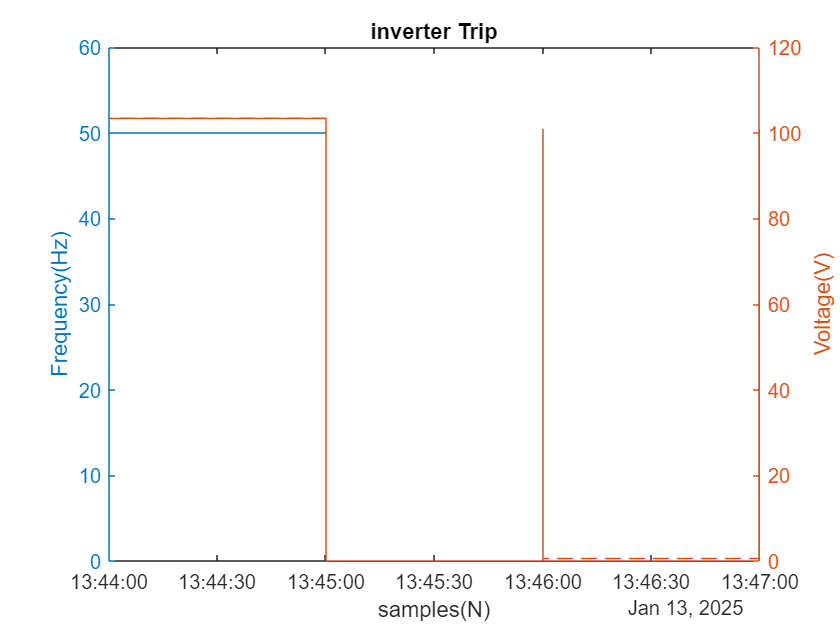

%Loss of grid event
Fgrid=T.Fgrid;
Fgrid_min=45;
%assert(all(T.Fgrid<45),'There was a power outage');
if any(Fgrid < Fgrid_min)
   [loc]=find(Fgrid<Fgrid_min);
   time_stamp=T.EventTime(loc(1));
   fprintf("There was a Power Outage at : %s\n",time_stamp)
   %check for inverter trip
   if(T.Vinv1_rms(loc(1)+10)<150)
       fprintf("Inverter Trip occured")
       figure
       title("inverter Trip")
       tmin=loc(1)-100;
       tmax=loc(1)+100;
       yyaxis left
       plot(time(tmin:tmax),Fgrid(tmin:tmax))
       ylabel("Frequency(Hz)")
       yyaxis right
       plot(time(tmin:tmax),T.Vinv1_rms(tmin:tmax))
       hold on
       plot(time(tmin:tmax),T.Vinv2_rms(tmin:tmax))
       hold off
       ylabel("Voltage(V)")
       xlabel("samples(N)")

   end
end

fprintf("Grid outage validated\n");

Grid outage validated


### PV Energy Production(kWh)

Epv=T.Epv;
if(Epv(end)<Epv(1)+10)
    fprintf("No PV Energy Generation\n");
else
    fprintf("Pv Energy Generated = %0.2f kWh\n",(Epv(end)-Epv(1))/1000);
end

Pv Energy Generated = 0.06 kWh


### Temperature Validation

#### Temperature Stats

% Assuming T is a structure containing the temperature data
Tinv_average = mean(T.Inv_t);
Tbat_average = mean(T.Batt_t);
Tpv_average = mean(T.Pv_t);
Tamb_average = mean(T.Amb_t);
TCM4_average = mean(T.Cm4_t);

Tinv_min = min(T.Inv_t);
Tbat_min = min(T.Batt_t);
Tpv_min = min(T.Pv_t);
Tamb_min = min(T.Amb_t);
TCM4_min = min(T.Cm4_t);

Tinv_max = max(T.Inv_t);
Tbat_max = max(T.Batt_t);
Tpv_max = max(T.Pv_t);
Tamb_max = max(T.Amb_t);
TCM4_max = max(T.Cm4_t);

% Create a table to display the results
temperature_data = table([Tinv_average; Tbat_average; Tpv_average; Tamb_average; TCM4_average], ...
                         [Tinv_min; Tbat_min; Tpv_min; Tamb_min; TCM4_min], ...
                         [Tinv_max; Tbat_max; Tpv_max; Tamb_max; TCM4_max], ...
    'VariableNames', {'Average (°C)', 'Min (°C)', 'Max (°C)'}, ...
    'RowNames', {'Inverter-temp', 'Battery-temp', 'PV-temp', 'Ambient-temp', 'CM4-temp'});

% Display the table
disp(temperature_data);

                     Average (°C)    Min (°C)    Max (°C)
                     ____________    ________    ________

    Inverter-temp       10.782          8.9        12.3  
    Battery-temp        9.8239          8.9        10.9  
    PV-temp              11.55            9        15.1  
    Ambient-temp         20.65         20.5        20.9  
    CM4-temp            42.123         40.8        43.8  





%Temp Design limits violations
%comment here after visualizing the plots and tables



### Evaluating Trips

#### Checking for Trip_1

fprintf("Analyzing Trip-1\n");

Analyzing Trip-1


analyze_trip1(T,time)

ans = 4×4 table
          Time                  TripCode                 TripName                    TripDescription           
    ________________    _________________________    _________________    _____________________________________

    13/01/2025 13:43    {'FLT 083832.SEInverter'}    {'Iinv1_OC_Trip'}    {'Over current on inverter phase 1.'}
    13/01/2025 13:43    {'FLT 083832.SEInverter'}    {'Iinv1_OC_Trip'}    {'Over current on inverter phase 1.'}
    13/01/2025 13:43    {'FLT 083833.SEInverter'}    {'Iinv2_OC_Trip'}    {'Over current on inverter phase 2.'}
    13/01/2025 13:45    {'FLT 083832.SEInverter'}    {'Iinv1_OC_Trip'}    {'Over current on inverter phase 1.'}


#### Checking for Trip_2

fprintf("Analyzing Trip-2\n");

Analyzing Trip-2


analyze_trip2(T,time)

ans = 2×4 table
          Time                  TripCode                    TripName                                         TripDescription                             
    ________________    ________________________    ________________________    _________________________________________________________________________

    13/01/2025 13:43    {'FLT 08848.SEInverter'}    {'DC_Component_Trip'   }    {'DC component of the grid current is greater than 1% of rated current.'}
    13/01/2025 13:43    {'FLT 08849.SEInverter'}    {'Phase1_overload_Trip'}    {'Overload occurred on inverter phase 1.'                               }


### Evaluating Alerts

#### Checking Alerts_1

fprintf("Analyzing Alerts-1\n");

Analyzing Alerts-1


analyze_alert1(T,time)

ans = 6×4 table
          Time                 AlertCode                        AlertName                                   AlertDescription                    
    ________________    ________________________    _________________________________    _______________________________________________________

    13/01/2025 13:45    {'WAR 08801.SEInverter'}    {'Grid_UV_Disconnection'        }    {'Grid Undervoltage warning'                          }
    13/01/2025 13:45    {'WAR 08803.SEInverter'}    {'Grid_UF_Disconnection'        }    {'Grid Under frequency warning'                       }
    13/01/2025 13:45    {'WAR 08806.SEInverter'}    {'Active_Method_Grid_Disconnect'}    {'Disconnected from the grid due to active islanding.'}
    13/01/2025 13:46    {'WAR 08801.SEInverter'}    {'Grid_UV_Disconnection'        }    {'Grid Undervoltage warning'     

#### Check for Alerts_2

fprintf("Analyzing Alerts-12\n");

Analyzing Alerts-12


analyze_alert2(T,time)

ans = 9×4 table
          Time                 AlertCode               AlertName                   AlertDescription           
    ________________    ________________________    ________________    ______________________________________

    13/01/2025 13:43    {'WAR 08820.SEInverter'}    {'PV3_UV_Alert'}    {'Gate Block PV3 converter due to UV'}
    13/01/2025 13:46    {'WAR 08818.SEInverter'}    {'PV1_UV_Alert'}    {'Gate Block PV1 converter due to UV'}
    13/01/2025 13:46    {'WAR 08820.SEInverter'}    {'PV3_UV_Alert'}    {'Gate Block PV3 converter due to UV'}
    13/01/2025 13:46    {'WAR 08818.SEInverter'}    {'PV1_UV_Alert'}    {'Gate Block PV1 converter due to UV'}
    13/01/2025 13:46    {'WAR 08819.SEInverter'}    {'PV2_UV_Alert'}    {'Gate Block PV2 converter due to UV'}
    13/01/2025 13:46    {'WAR 08820.SEInverter'}    {'PV3_UV_Alert'}  

## Control Status

CS=decode_controlStatus(T);